%restoredefaultpath;matlabrc

% <<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<
% data in the standardized (ftp) format  
% downloaded from sciebo: 
% https://gast.sciebo.de/index.php/apps/files?dir=/EEGManyPipelines/EMP%20time%20series%20exp/TimelockAVG
project_path = 'C:\Users\root\Desktop\EMP_tmp2'
% <<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<
data_dir = fullfile(project_path, "TimelockAVG")

cd(data_dir)
team_list = dir('sbjavg*.mat')  % 76 teams

load('CHAN_cell.mat')
    disp(chan_cell{1})
    disp(chan_cell{32})
    %chan_cell = alldatavg{1,1}.label

load('TIME_vector.mat')
    disp(time_vector(1:length(time_vector)-1:end))
    disp(time_vector(52))
    %time_vector = alldatavg{1,1}.time

n_chan = length(chan_cell);
n_sample = length(time_vector);
n_subj = 33;


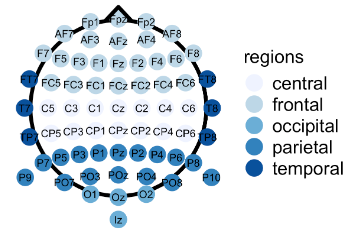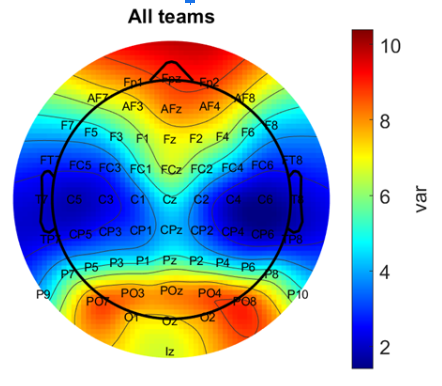

data_avg_allteam =[];
data_median_allteam =[];
data_var_allteam =[];
%data_var2_allteam =[]; % nanstd
%data_var3_allteam =[]; % nanmad


% <<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<
% plot team-ERP for a specific channel
i_chan = 32 %CPz
%i_chan = 33 %FPz 
%%i_chan = 34 %FPz 
% <<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<<

% cycle across all teams
for i_team=1:length(team_list)
    %ii=71
    team_name = team_list(i_team).name(1:end-4)
    load(fullfile(data_dir, team_list(i_team).name));

    % initialize 3d arrays with NaN
    data_team_allsubj = NaN(n_subj, n_chan, n_sample);
    data_var_allsubj = NaN(n_subj, n_chan, n_sample);
    position_tmp_orig =[];

    for i_subj = 1:size(alldatavg,2)
        
        if ~isempty(alldatavg{1,i_subj})

            % find corresponding channel position:
            position_tmp =[];
            [~, position_tmp] = ismember(chan_cell, alldatavg{1,i_subj}.label);
            %chan_cell{i_chan}
            alldatavg{1,i_subj}.label(position_tmp(i_chan))
            if i_subj ==1; position_tmp_orig = position_tmp; end
    
            if isequal(position_tmp_orig, position_tmp)
            if length(position_tmp) == n_chan 
            %if isequal(alldatavg{1,i_subj}.label, chan_cell)
                data_avg_tmp =[];
                data_avg_tmp = alldatavg{1,i_subj}.avg;
                % re-order the data_avg 2d (chan x timepoint) 
                % with a common channel vector
                data_team_allsubj(i_subj,:,:) = data_avg_tmp(position_tmp,:);

                data_var_tmp =[];
                data_var_tmp = alldatavg{1,i_subj}.var;
                data_var_allsubj(i_subj,:,:) = data_var_tmp(position_tmp,:);

            else
                disp([ '!!! problem with CHAN in: ' team_name ' subj: ' num2str(i_subj)])
            end; end

        else
            disp(['!!! subj ' num2str(i_subj) ' in ' team_name ' = NaN'])
        end
    end
    
%     % find NAN values
%     nan_logical = isnan(data_team_allsubj);
%     nan_indices = find(nan_logical);
%     %sum(sum(isnan(data_avg_allteam)))
% 
%     % Convert linear indices to subscripts (x, y, z positions)
%     [x, y, z] = ind2sub(size(data_team_allsubj), nan_indices);
%     % Display the positions of NaN values
%     disp('Positions of NaN values:');
%     disp([x, y, z]);

    data_avg_allteam(i_team,:,:) = squeeze(nanmean(data_team_allsubj,1));
    data_median_allteam(i_team,:,:) = squeeze(nanmedian(data_team_allsubj,1));
    
    data_var_allteam(i_team,:,:) = squeeze(nanmedian(data_var_allsubj,1));
    %data_var2_allteam(i_team,:,:) = squeeze(nanstd(data_var_allsubj,1));
    %data_var3_allteam(i_team,:,:) = squeeze(mad(data_var_allsubj,1,1));
    
    % PLOT - - - - - - - - - - - - 
    figure(1); hold on
    plot(time_vector, squeeze(data_avg_allteam(i_team,i_chan,:)))

    figure(2); hold on
    
    plot(time_vector, squeeze(data_var_allteam(i_team,i_chan,:)))
end

%legend

figure(1); hold on
plot(time_vector, squeeze(nanmedian(data_avg_allteam(:,i_chan,:),1)), 'k', 'Linewidth', 3)
plot(time_vector, squeeze(nanmedian(data_median_allteam(:,i_chan,:),1)), 'k--', 'Linewidth', 3)
ylim([-20 20])

figure(2); hold on
plot(time_vector, squeeze(nanmedian(data_var_allteam(:,i_chan,:),1)), 'k', 'Linewidth', 3)
ylim([0 200])


CPz

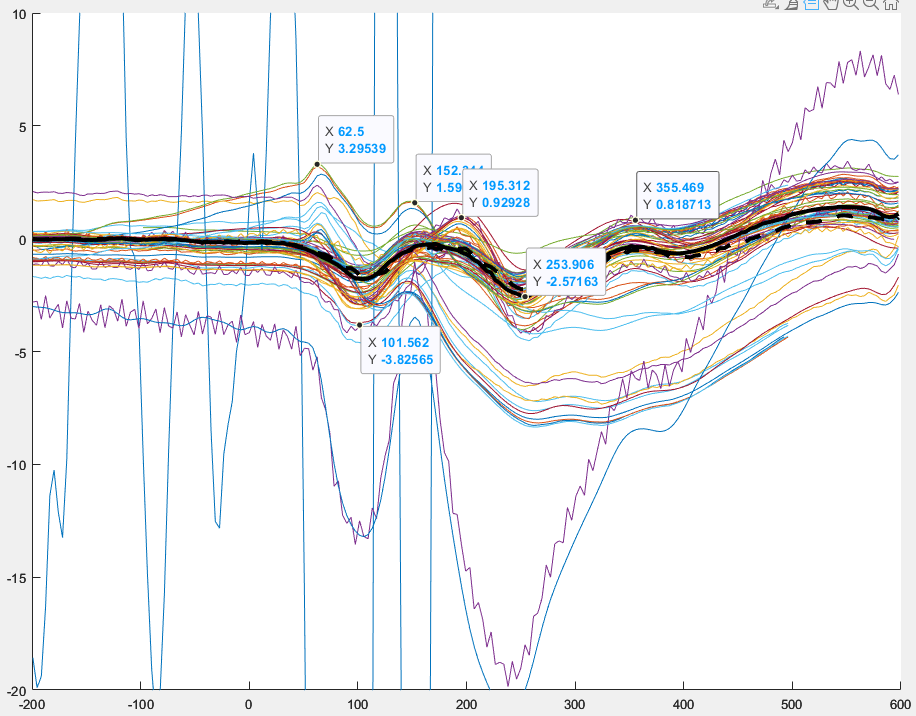


% TO CHECK !!!!!
xxx = isnan(data_avg_allteam(:,1,1))

'sbjavg_1559fd3bafe5582c'

'sbjavg_223dfd3c429d0e79'

'sbjavg_26ab3771b0c195f5'

'sbjavg_3dc2c5916354971b'

'sbjavg_841f7d890725a452'

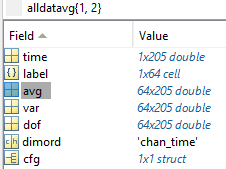    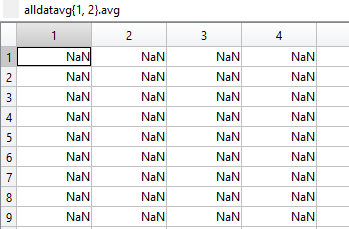

'sbjavg_3c8c07696fbd0314'

'sbjavg_CognitiveSystems-KU'

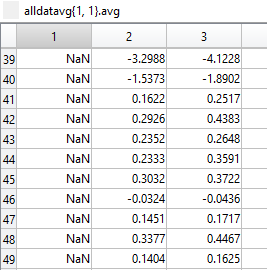timepoint

'sbjavg_ee3fdc470061d8db'

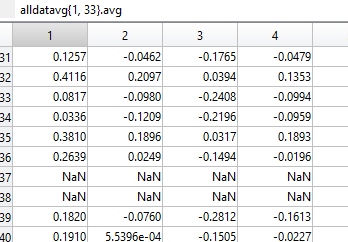channel

## distance metrics from prototypical PIPELINE

structure:

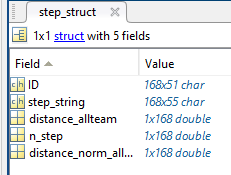

% LOAD pipeline distance matrics
distance_dir = fullfile(project_path, '_corr_ERP_DISTANCE_graph')
% step_struct
load(fullfile(distance_dir, "distance_from_graph_path_ref_BCFHMN.mat"))

% - - - - - -  - - --  - - -
% extract distance value for each team in the team_list
distance_vector = NaN([length(team_list), 1]);
distance_norm_vector = NaN([length(team_list), 1]);
distance_step_vector = NaN([length(team_list), 1]);

step_struct_ID = cellstr(step_struct.ID);

for i_team =1:length(team_list)
    team_name = team_list(i_team).name(8:end-4)

    for kk=1:length(step_struct.ID)
        %kk=2
        if contains(step_struct_ID{kk,1}, team_name)
            disp(step_struct_ID{kk,1})

            distance_vector(i_team,1) = step_struct.distance_allteam(kk);
            distance_norm_vector(i_team,1) = step_struct.distance_norm_allteam(kk);
            distance_step_vector(i_team,1) = step_struct.n_step(kk);
            %index = strcmp({step_struct.ID}, team_name)
        end
    end
end



## time window of interest 

based on the ERP_avg response


% in msec - - - - - - - -
%ERP_toi0 = 60 %in msec
ERP_toi1 = 90 %100 %90 %in msec: first NEGative peak
ERP_toi2 = 160 %170 %160 %in msec: first POSitive peak
%ERP_toi3 = 250 %in msec: 
%ERP_toi4 = 350 %in msec: 
%ERP_toi6 = 550 %in msec

delta_toi = 30 %msec

% convert into sample: - - - - - - - - - - 
%[ ~, ERP_soi0 ] = min(abs(time_vector - ERP_toi0))
[ ~, ERP_soi1 ] = min(abs(time_vector - ERP_toi1))
[ ~, ERP_soi2 ] = min(abs(time_vector - ERP_toi2))
%[ ~, ERP_soi3 ] = min(abs(time_vector - ERP_toi3))
%[ ~, ERP_soi4 ] = min(abs(time_vector - ERP_toi4))

delta_soi = floor(delta_toi / (1/250*1000))


## compute robust correlation AT SINGLE SUBJECT level

addpath(genpath('C:\Users\root\Desktop\EMP_tmp2\Corr_toolbox_v2'))

n_subj = 33
n_chan = length(chan_cell);
n_sample = length(time_vector);
n_team = length(team_list)

peak_vector =NaN([n_chan, n_subj, 10]);  %for storing all the results
%peak_vector =[]  %for storing all the results

%figure; hold on

for i_subj = 1:n_subj
%for i_subj = 2:n_subj
%for i_subj=3

    data_avg_singlesubj = NaN(n_team, n_chan, n_sample);
    data_var_singlesubj = NaN(n_team, n_chan, n_sample);

    for i_team=1:length(team_list)
        %ii=71
        team_name = team_list(i_team).name(1:end-4)
        load(fullfile(data_dir, team_list(i_team).name));  %-> alldataavg

        position_tmp_orig =[];

        if ~isempty(alldatavg{1,i_subj})

            % find corresponding channel position:
            position_tmp =[];
            [~, position_tmp] = ismember(chan_cell, alldatavg{1,i_subj}.label);
            %chan_cell{i_chan}
            alldatavg{1,i_subj}.label(position_tmp(i_chan))
            if i_subj ==1; position_tmp_orig = position_tmp; end
    
            %if isequal(position_tmp_orig, position_tmp)
            if length(position_tmp) == n_chan 
            %if isequal(alldatavg{1,i_subj}.label, chan_cell)
                data_avg_tmp =[];
                data_avg_tmp = alldatavg{1,i_subj}.avg;
                data_avg_singlesubj(i_team,:,:) = data_avg_tmp(position_tmp,:);
                    
                    figure(40); subplot(5,7,i_subj); hold on
                    chan_tmp = 32
                    plot(time_vector, squeeze(data_avg_singlesubj(i_team,chan_tmp,:)))
                    ylim([-20 20])
                    %figure; imagesc(data_avg_tmp)
                    %figure; imagesc(squeeze(data_avg_singlesubj(i_team-1,:,:)))

                    if i_team == n_team
                        plot(time_vector, nanmedian(squeeze(data_avg_singlesubj(:,chan_tmp,:)),1), 'k-', 'LineWidth', 3)
                    end
                data_var_tmp =[];
                data_var_tmp = alldatavg{1,i_subj}.var;
                data_var_singlesubj(i_team,:,:) = data_var_tmp(position_tmp,:);

            else
                disp([ '!!! problem with CHAN in: ' team_name ' subj: ' num2str(i_subj)])
            end; %end

        else
            disp(['!!! subj ' num2str(i_subj) ' in ' team_name ' = NaN'])
        end
    end


    for i_chan = 1:n_chan
        %i_chan = 32

        % #################################################
        % find PEAKs of interest (for a single channel)
        % help imregionalmax
        % #################################################
        data_median_singlesubj = nanmedian(squeeze(data_avg_singlesubj(:,i_chan,:)),1);
        % Compute derivative with respect to x
        dy = [ 0 diff(data_median_singlesubj) ./ diff(1:length(time_vector))]; 
            if i_chan ==32
                figure(50); subplot(5,7,i_subj); hold on
                plot(dy, '--'); hold on; plot(data_median_singlesubj)
                %figure; plot(time_vector, dy); hold on; plot(time_vector, data_median_singlesubj)
            end

        %find 1° NEGative peak close to ERP_toi1
        % with derivative ~ 0 
        soi_tmp = ERP_soi1-delta_soi : ERP_soi1+delta_soi;
        idx_tmp = imregionalmin(data_median_singlesubj(soi_tmp));
        % if there are more than one peak
        % find the peak with highest abs value
        if length(soi_tmp(idx_tmp))>1
            [~, idx_tmp2] = min(data_median_singlesubj(soi_tmp(idx_tmp)));
            val_tmp = soi_tmp(idx_tmp);
            peak_vector(i_chan,i_subj,1) = val_tmp(idx_tmp2);
        else
            peak_vector(i_chan,i_subj,1) = soi_tmp(idx_tmp);
        end
        peak_vector(i_chan,i_subj,2) = data_median_singlesubj(peak_vector(i_chan,i_subj,1));
        peak_vector(i_chan,i_subj,3) = dy(peak_vector(i_chan,i_subj,1));
    

        %find 1° POSitive peak close to ERP_toi2
        soi_tmp = ERP_soi2-delta_soi : ERP_soi2+delta_soi;
        idx_tmp = imregionalmax(data_median_singlesubj(soi_tmp));
        if length(soi_tmp(idx_tmp))>1
            [~, idx_tmp2] = max(data_median_singlesubj(soi_tmp(idx_tmp)));
            val_tmp = soi_tmp(idx_tmp);
            peak_vector(i_chan,i_subj,6) = val_tmp(idx_tmp2);
        else
            peak_vector(i_chan,i_subj,6) = soi_tmp(idx_tmp);
        end
        peak_vector(i_chan,i_subj,7) = data_median_singlesubj(peak_vector(i_chan,i_subj,6));
        peak_vector(i_chan,i_subj,8) = dy(peak_vector(i_chan,i_subj,6));
        
            if i_chan ==32
                figure(50); subplot(5,7,i_subj); hold on
                scatter(peak_vector(i_chan,i_subj,1), peak_vector(i_chan,i_subj,2), 25, 'r', 'filled')
                scatter(peak_vector(i_chan,i_subj,6), peak_vector(i_chan,i_subj,7), 25, 'r', 'filled')
            end
            
        % #################################################
        % compute (ROBUST) CORRELATION (for a single channel)
        % at the peaks of interest
        % #################################################
        fig_flag = 0;

        % 1° NEGative peak
        data_avg_tmp =[];
        data_avg_tmp = data_avg_singlesubj(:,i_chan, peak_vector(i_chan,i_subj,1));
    
        data_var_tmp = data_var_singlesubj(:,i_chan, peak_vector(i_chan,i_subj,1));
    
        %data_mean_tmp = nanmean(data_avg_tmp);
        %data_dist_fromavg = data_avg_tmp - data_mean_tmp; 
        %data_absdist_fromavg = abs(data_avg_tmp - data_mean_tmp); 
        %data_dist_frommedian = data_avg_tmp - nanmedian(data_avg_tmp);; 
    
%         [corr_value_tmp, p_value_tmp]= corrcoef(data_avg_tmp, distance_vector, 'Rows', 'complete');
%         peak_vector(i_chan,i_subj,4) = corr_value_tmp(1,2);
%         peak_vector(i_chan,i_subj,5) = p_value_tmp(1,2);
        
        corr_value_array = [ data_avg_tmp, distance_vector ];
        % remove NaN
        corr_value_array(any(isnan(corr_value_array), 2), :) = [];
        fig_flag = 0;
        [r,t,p] = Spearman(corr_value_array(:,1), corr_value_array(:,2), fig_flag,0.05);
        peak_vector(i_chan,i_subj,4) = r;
        peak_vector(i_chan,i_subj,5) = p;


        % also for VARIANCE ??
        
    
        % - - - - - - - -  -- - - - - - - 
        % 1° POSitive peak
        data_avg_tmp =[];  data_var_tmp =[];
        data_avg_tmp = data_avg_singlesubj(:,i_chan, peak_vector(i_chan,i_subj,6));
            %data_avg_tmp =  data_avg_singlesubj(:,i_chan, 98)

        data_var_tmp = data_var_singlesubj(:,i_chan, peak_vector(i_chan,i_subj,6));
    
%         [corr_value_tmp, p_value_tmp]= corrcoef(data_avg_tmp, distance_vector, 'Rows', 'complete');
%         peak_vector(i_chan,i_subj,9) = corr_value_tmp(1,2);
%         peak_vector(i_chan,i_subj,10) = p_value_tmp(1,2);

        corr_value_array = [ data_avg_tmp, distance_vector ];
        % remove NaN
        corr_value_array(any(isnan(corr_value_array), 2), :) = [];
        %fig_flag = 1;
        [r,t,p] = Spearman(corr_value_array(:,1), corr_value_array(:,2), fig_flag,0.05);
        peak_vector(i_chan,i_subj,9) = r;
        peak_vector(i_chan,i_subj,10) = p;

    end
end



## check the results


% The slope of the line can be set to the correlation value
% For simplicity, let's plot a line with the slope equal to r
%y = r * x; % Line equation y = r * x

%chan_tmp = 32
%peak_vector_tmp = squeeze(peak_vector(chan_tmp,:,:));
%peak_vector_tmp = squeeze(peak_vector(:,i_subj,:));


subj_vector = 1:33
% !!!!!!!
% subjects to remove (for now)  since the peak detection didn't work
subj_vector([16,19,20,23,28,30]) = [];
for i_chan = 1:n_chan
    peak_vector_tmp =[];
    peak_vector_tmp = squeeze(peak_vector(i_chan,:,:));

    if median(peak_vector_tmp(subj_vector, 4)) > 0
            [ ~, ERP_pval(i_chan,1) ] = ttest(peak_vector_tmp(subj_vector, 4), 0);
    else
            ERP_pval(i_chan,1) = NaN;
    end
    
    if median(peak_vector_tmp(subj_vector, 9)) < 0
            %[h, p] = ttest(peak_vector_tmp(subj_vector, 9), 0)
            [ ~, ERP_pval(i_chan,2) ] = ttest(peak_vector_tmp(subj_vector, 9), 0);
    else
            ERP_pval(i_chan,2) = NaN;
    end

end

figure(100); 
for i_subj = subj_vector
    disp(i_subj)

    slope_tmp = peak_vector_tmp(i_subj, 4);
    subplot(121); hold on
    xx = 1:3;
    plot(slope_tmp*xx)

    slope_tmp = peak_vector_tmp(i_subj, 9);
    if median(slope_tmp) > 0
        [ ~, ERP_1_pval(i_chan) ] = ttest(slope_tmp, 0);
    else
        ERP_1_pval(i_chan) = NaN;
    end
    subplot(122); hold on
    xx = 4:6
    plot(slope_tmp*xx)
end


    



    % - - - - -- - - - - - - - - 
    % compute ROBUST CORRELATION with NaN ??
    corr_avg_pipedist_singlesubj = NaN([n_chan, n_sample]);
    pval_avg_pipedist_singlesubj = NaN([n_chan, n_sample]);
    
    corr_meandist_pipedist_singlesubj = NaN([n_chan, n_sample]);
    pval_meandist_pipedist_singlesubj = NaN([n_chan, n_sample]);

    corr_mediandist_pipedist_singlesubj = NaN([n_chan, n_sample]);
    pval_mediandist_pipedist_singlesubj = NaN([n_chan, n_sample]);

    corr_meanabsdist_pipedist_singlesubj = NaN([n_chan, n_sample]);
    pval_meanabsdist_pipedist_singlesubj = NaN([n_chan, n_sample]);
   
    corr_var_pipedist_singlesubj = NaN([n_chan, n_sample]);
    pval_var_pipedist_singlesubj = NaN([n_chan, n_sample]);

    for i_chan =1:n_chan
        
        for i_sample = 1:n_sample

            %i_chan = chan_tmp; i_sample = 77
            %i_chan = chan_tmp; i_sample = 98

            data_avg_tmp = data_avg_singlesubj(:,i_chan,i_sample);
%                 if do_plot
                     figure; scatter(distance_vector, data_avg_tmp)
                     hold on; yline(nanmedian(data_avg_tmp), 'k--')
%                 end
            
            data_var_tmp = data_var_singlesubj(:,i_chan,i_sample);

            data_mean_tmp = nanmean(data_avg_tmp);
            data_dist_fromavg = data_avg_tmp - data_mean_tmp; 
            data_absdist_fromavg = abs(data_avg_tmp - data_mean_tmp); 

            data_dist_frommedian = data_avg_tmp - nanmedian(data_avg_tmp);; 
            
            %corr_result = robust_correlation(distance_vector, data_tmp);
            [corr_value_tmp, p_value_tmp]= corrcoef(data_avg_tmp, distance_vector, 'Rows', 'complete');
            corr_avg_pipedist_singlesubj(i_chan, i_sample) = corr_value_tmp(1,2);
            pval_avg_pipedist_singlesubj(i_chan, i_sample) = p_value_tmp(1,2);

            [corr_value_tmp, p_value_tmp]= corrcoef(data_dist_fromavg, distance_vector, 'Rows', 'complete');
            corr_meandist_pipedist_singlesubj(i_chan, i_sample) = corr_value_tmp(1,2);
            pval_meandist_pipedist_singlesubj(i_chan, i_sample) = p_value_tmp(1,2);
                if do_plot
                figure; scatter(data_dist_fromavg, distance_vector)
                title(['pval: ' num2str(p_value_tmp(1,2)) ' (' num2str(corr_value_tmp(1,2))])
                end

            [corr_value_tmp, p_value_tmp]= corrcoef(data_absdist_fromavg, distance_vector, 'Rows', 'complete');
                if do_plot
                figure; scatter(data_absdist_fromavg, distance_vector)
                title(['pval: ' num2str(p_value_tmp(1,2)) ' (' num2str(corr_value_tmp(1,2))])
                end
            corr_meanabsdist_pipedist_singlesubj(i_chan, i_sample) = corr_value_tmp(1,2);
            pval_meanabsdist_pipedist_singlesubj(i_chan, i_sample) = p_value_tmp(1,2);

            [corr_value_tmp, p_value_tmp]= corrcoef(data_dist_frommedian, distance_vector, 'Rows', 'complete');
                if do_plot
                figure; scatter(distance_vector, data_dist_frommedian)
                title(['pval: ' num2str(p_value_tmp(1,2)) ' (' num2str(corr_value_tmp(1,2))])
                hold on; yline(nanmedian(data_avg_tmp), 'k--')
                end
            corr_mediandist_pipedist_singlesubj(i_chan, i_sample) = corr_value_tmp(1,2);
            pval_mediandist_pipedist_singlesubj(i_chan, i_sample) = p_value_tmp(1,2);

            [corr_value_tmp, p_value_tmp]= corrcoef(data_var_tmp, distance_vector, 'Rows', 'complete');
            corr_var_pipedist_singlesubj(i_chan, i_sample) = corr_value_tmp(1,2);
            pval_var_pipedist_singlesubj(i_chan, i_sample) = p_value_tmp(1,2);

        end
    end
           
%     figure(20); hold on 
%     %subplot 211; imagesc(corr_singlesubj)
%     subplot(5,7,i_subj); imagesc(pval_avg_pipedist_singlesubj); 
%     ax = gca; ax.CLim = [0 0.2]; %colorbar
%     title([ 's ' num2str(i_subj)])
% 
%     figure(21); hold on 
%     %subplot 211; imagesc(corr_singlesubj)
%     subplot(5,7,i_subj); imagesc(pval_var_pipedist_singlesubj); 
%     ax = gca; ax.CLim = [0 0.2]; %colorbar
%     title([ 's ' num2str(i_subj)])
% 
%     figure(22); hold on 
%     %subplot 211; imagesc(corr_singlesubj)
%     subplot(5,7,i_subj); imagesc(pval_meandist_pipedist_singlesubj); 
%     ax = gca; ax.CLim = [0 0.2]; %colorbar
%     title([ 's ' num2str(i_subj)])
% 
%     figure(23); hold on 
%     %subplot 211; imagesc(corr_singlesubj)
%     subplot(5,7,i_subj); imagesc(pval_meanabsdist_pipedist_singlesubj); 
%     ax = gca; ax.CLim = [0 0.2]; %colorbar
%     title([ 's ' num2str(i_subj)])
% 
%     figure(24); hold on 
%     %subplot 211; imagesc(corr_singlesubj)
%     subplot(5,7,i_subj); imagesc(pval_mediandist_pipedist_singlesubj); 
%     ax = gca; ax.CLim = [0 0.2]; %colorbar
%     title([ 's ' num2str(i_subj)])

    figure(25); hold on; colormap(jet)
    [row, col] = find(pval_meandist_pipedist_singlesubj <0.2);
    corr_mask = NaN([n_chan, n_sample]);
    for hh=1:length(row)
        corr_mask(row(hh),col(hh)) = corr_meandist_pipedist_singlesubj(row(i_team),col(i_team));
    end
    %figure; colormap(hot); imagesc(corr_mask); colorbar
    subplot(5,7,i_subj); imagesc(corr_mask); colorbar

end

subplot(5,7,5*7); axis off; ax = gca; ax.CLim = [0 0.2]; colorbar

% - - - - - - - - - - 
% ROBUST CORRELATION:
addpath(genpath('C:\Users\root\Desktop\EMP_tmp2\Corr_toolbox_v2'))

corr_value_array_98 = [ distance_vector, data_avg_tmp ]
%corr_value_array = [ distance_vector, data_avg_tmp ]
corr_value_array = corr_value_array_98
results = robust_correlation(corr_value_array(:,1), corr_value_array(:,2))

%     % find NAN values
%     nan_logical = isnan(data_team_allsubj);
%     nan_indices = find(nan_logical);
%     %sum(sum(isnan(data_avg_allteam)))
% 
%     % Convert linear indices to subscripts (x, y, z positions)
%     [x, y, z] = ind2sub(size(data_team_allsubj), nan_indices);
%     % Display the positions of NaN values
%     disp('Positions of NaN values:');
%     disp([x, y, z]);

end

%     data_avg_allteam(ii,:,:) = squeeze(nanmean(data_team_allsubj,1));
%     data_median_allteam(ii,:,:) = squeeze(nanmedian(data_team_allsubj,1));
%     
%     data_var_allteam(ii,:,:) = squeeze(nanmedian(data_var_allsubj,1));
%     data_var2_allteam(ii,:,:) = squeeze(nanstd(data_var_allsubj,1));
%     data_var3_allteam(ii,:,:) = squeeze(mad(data_var_allsubj,1,1));
% 
%     plot(time_vector, squeeze(data_avg_allteam(ii,i_chan,:)))
% end
